# Tests for debugging purposes

## The equations

## 
$$g(X,Q) = \sum_j \|X-Y_jQ_j\|^2 
\\
\nabla g(X,Q) = 2\bigg(\sum_j(X-Y_jQ_j), Y^\top(YQ-X)\bigg)
\\
\nabla^2 g(X,Q)[U,V] = \nabla g(U,V)$$


## Nonconvex problem

### Gradient

The slope should be 2. It appears to be: 2.00001.
If it is far from 2, then directional derivatives might be erroneous.


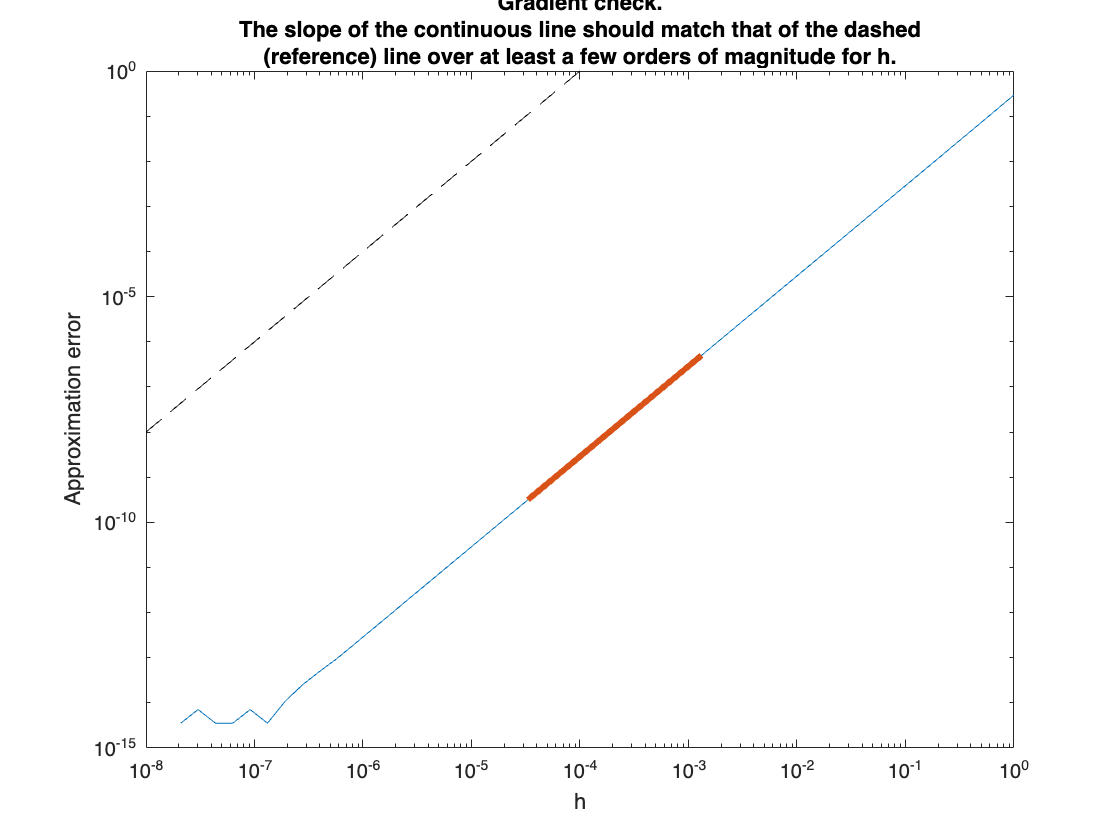

The residual should be 0, or very close. Residual: 1.51208e-15.
If it is far from 0, then the gradient is not in the tangent space.
In certain cases (e.g., hyperbolicfactory), the tangency test is inconclusive.


clear
n=5; % data dimension
k=5; % number of matrices
r=round(n/2); % size of factorization Y of data A
p=r+1; % size of factorization X of barycenter B (r<=p)
A = data(n,k,r);
prob = nonconvex_problem(A,r,p);

checkgradient(prob);

### Hessian

checkhessian(prob);

The slope should be 3. It appears to be: 3.00036.
If it is far from 3, then directional derivatives,
the gradient or the Hessian might be erroneous.
Tangency residual should be zero, or very close; residual: 3.04147e-16.
If it is far from 0, then the Hessian is not in the tangent space.
||a*H[d1] + b*H[d2] - H[a*d1+b*d2]|| should be zero, or very close.
	Value: 4.53142e-16 (norm of H[a*d1+b*d2]: 1.66209)
If it is far from 0, then the Hessian is not linear.
<d1, H[d2]> - <H[d1], d2> should be zero, or very close.
	Value: 0.0930706 - 0.0930706 = 6.93889e-17.
If it is far from 0, then the Hessian is not symmetric.


### Optimization

clear
n=32; % data dimension
k=10; % number of matrices
r=round(n/2); % size of factorization Y of data A
p=r+5; % size of factorization X of barycenter B (r<=p)
A = data(n,k,r);
prob = nonconvex_problem(A,r,p);

options.debug=0;
%options.statsfun = @variance_statsfun;
[x, xcost, info, options] = trustregions(prob,[],options);

           iter                  cost val     grad. norm    numinner     hessvec   numstored   stopreason
              0   +1.1741059303963859e+03   7.321077e+01
acc TR+       1   +9.3360429329473743e+02   6.173398e+01           1           1           1   exceeded trust region
acc TR+       2   +5.9370382605998736e+02   3.804584e+01           1           1           1   exceeded trust region
acc TR+       3   +3.5476498809330803e+02   1.343351e+01           2           2           2   negative curvature
REJ TR-       4   +3.5476498809330803e+02   1.343351e+01           2           2           2   exceeded trust region
acc TR+       5   +3.1429096340154911e+02   1.471360e+01           1           0           2   exceeded trust region
REJ TR-       6   +3.1429096340154911e+02   1.471360e+01           3           3           2   exceeded trust region
acc TR+       7   +2.8896724432634579e+02   9.330497e+00           1           0           2   exceeded trust region
acc           8   +2.

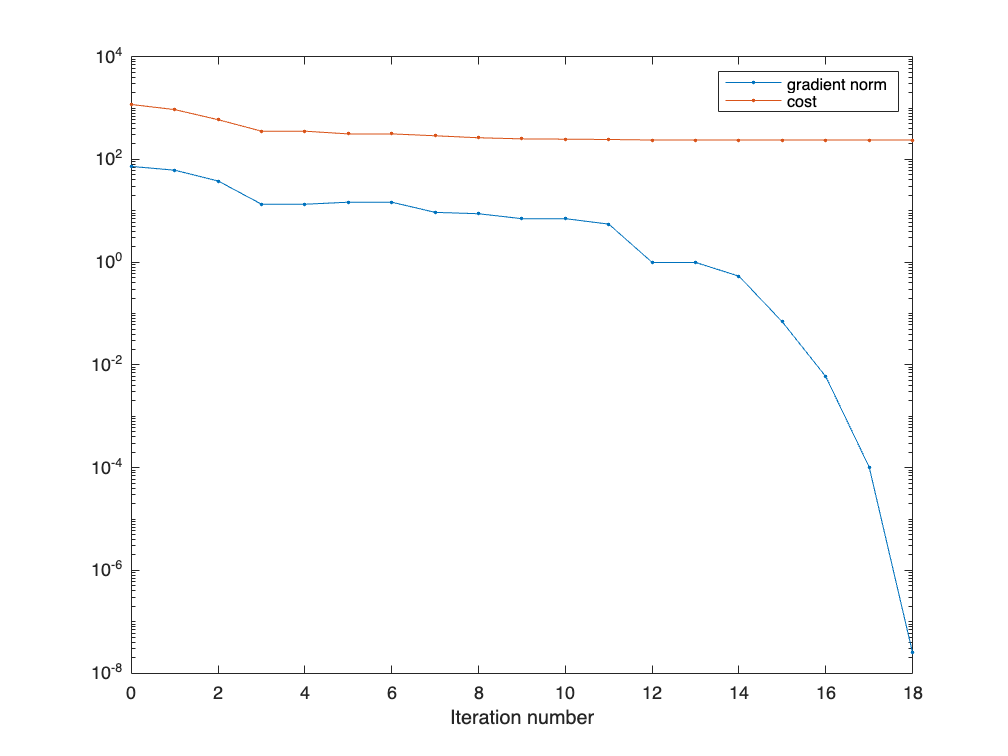

figure;
semilogy([info.iter], [info.gradnorm], '.-',[info.iter],[info.cost],'.-');
xlabel('Iteration number');
legend("gradient norm","cost")

## Convex problem

### Gradient

The slope should be 2. It appears to be: 2.00411.
If it is far from 2, then directional derivatives might be erroneous.


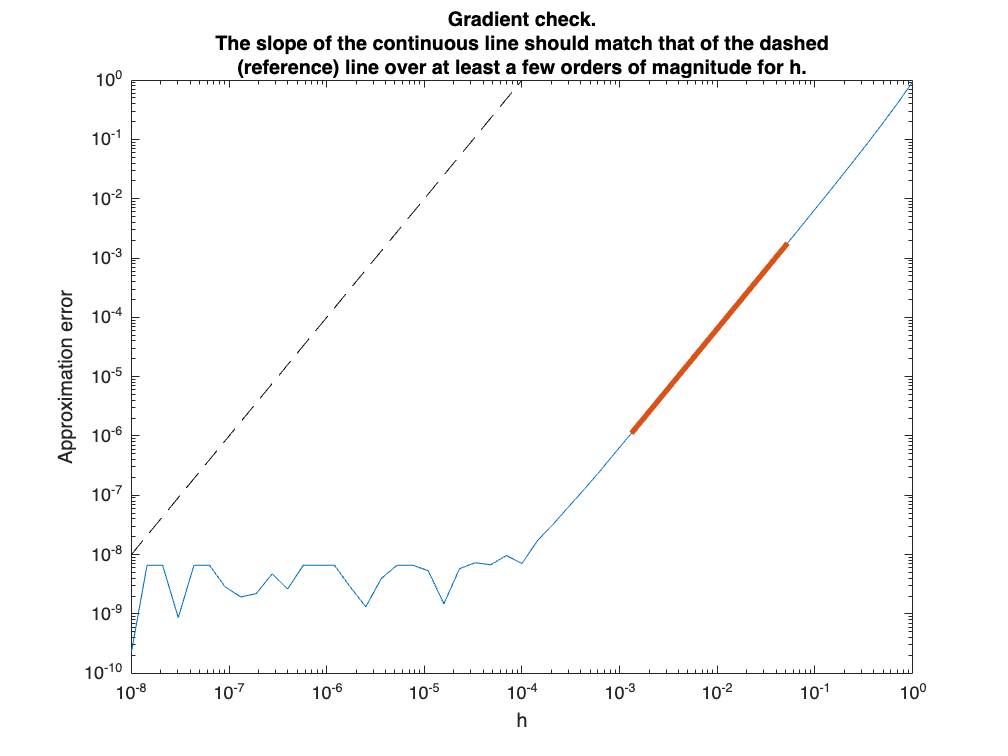

The residual should be 0, or very close. Residual: 1.18678e-18.
If it is far from 0, then the gradient is not in the tangent space.
In certain cases (e.g., hyperbolicfactory), the tangency test is inconclusive.


clear
n=2; % data dimension
k=4; % number of matrices
A = data(n,k,n-1);
prob2 = convex_problem(A);

checkgradient(prob2);

### Manopt optimization

clear
n=4; % data dimension
k=10; % number of matrices
A = data(n,k,2);
prob2 = convex_problem(A);

% options.debug=1;
% options.statsfun = @variance_statsfun;
[x, xcost, info, options] = trustregions(prob2);

           iter                  cost val     grad. norm    numinner     hessvec   numstored   stopreason
              0   +7.3514000113140892e+00   1.136896e+00
acc TR+       1   +6.9801293382246401e+00   7.855855e-01           1           1           1   exceeded trust region
acc TR+       2   +6.5916319178880656e+00   3.802273e-01           2           2           2   exceeded trust region
acc           3   +6.4562366877154647e+00   1.900381e-01           2           2           2   reached target residual-kappa (linear)
acc           4   +6.3863537638623660e+00   1.034624e-01           3           3           2   reached target residual-kappa (linear)
acc           5   +6.3526552366076876e+00   5.215556e-02           3           3           3   reached target residual-kappa (linear)
acc           6   +6.3365318511834383e+00   2.673420e-02           5           5           3   reached target residual-theta (superlinear)
acc           7   +6.3294130603446863e+00   1.303114e-02      

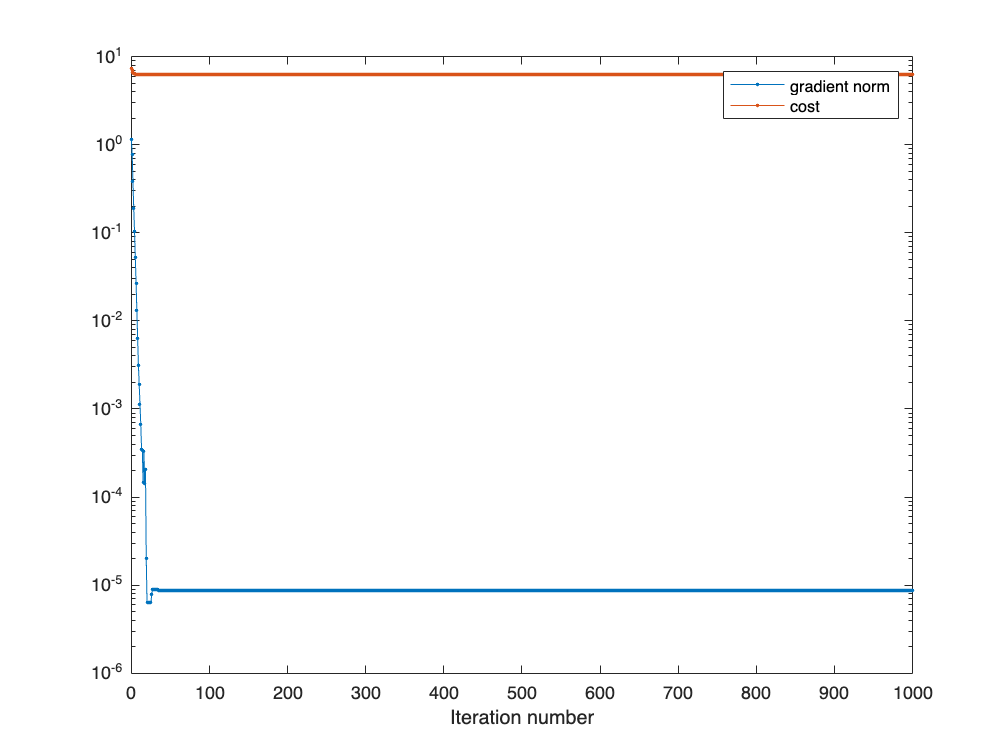

figure;
semilogy([info.iter], [info.gradnorm], '.-',[info.iter],[info.cost],'.-');
xlabel('Iteration number');
legend("gradient norm","cost")

### CVX optimization

clear
n=2; % data dimension
k=1000; % number of matrices
r=n;
A = data(n,k,r);
[B,Bcost,info] = cvx_solve(A)

B =     1.3342    0.0976
    0.0976    1.2974


Bcost = 1.3710

info = struct with fields:
      cost: 1.3710
    status: 'Solved'
      iter: 13
       tol: 2.5116e-09
    optbnd: 1.3710
      time: 38.2700


fprintf("%e\n",eig(B))

1.216471e+00
1.415151e+00


fprintf("%e\n",eig(A(:,:,1)))

2.458212e+00
4.100170e+00


### Fast vs slow version

clear
Nreapeat = 5;
nn=2; % data dimension
kk=round(linspace(1,50,5)); % number of matrices
for jn=1:length(nn)
    n=nn(jn);
    r=n;
    for jk=1:length(kk)
        k=kk(jk);
        A = data(n,k,r);
        for rep=1:Nreapeat
            [B,Bcost,info] = cvx_solve(A,"fast");
            time.fast(jn,jk,rep)=info.time;
            [B_slow,Bcost_slow,info_slow] = cvx_solve(A,"slow");
            time.slow(jn,jk,rep)=info_slow.time;
            Berr(jn,jk,rep) = norm(B-B_slow,"fro") / norm(B_slow,"fro");
        end
    end
end

max(Berr,[],"all")

ans = 2.8590e-05

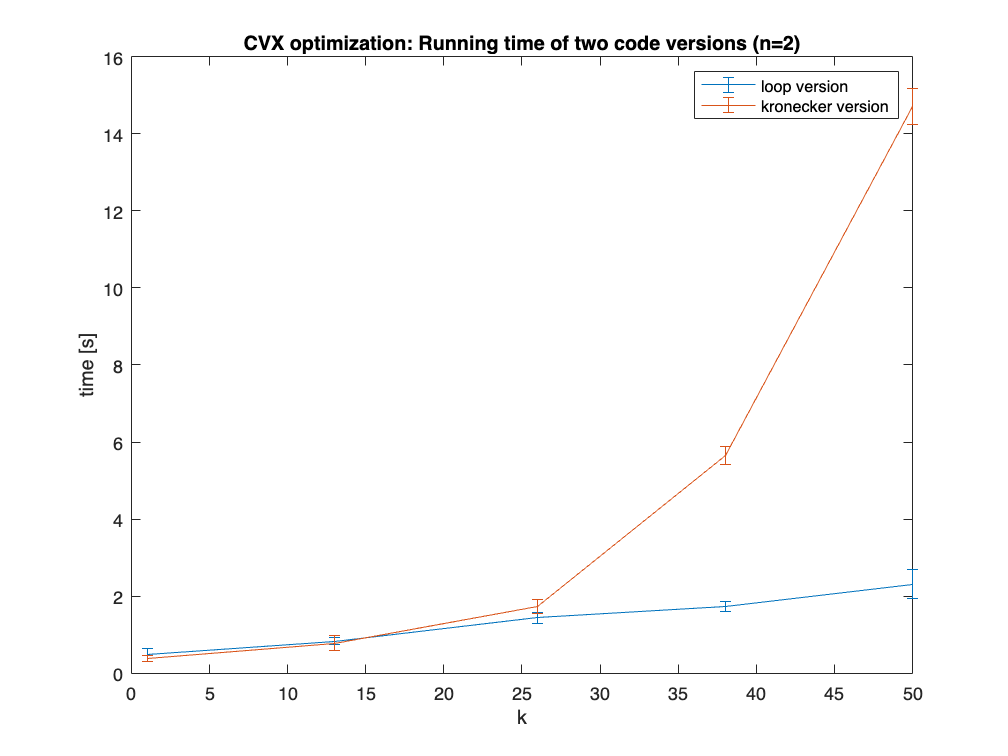

[sigma.slow,mu.slow] = std(time.slow,0,3);
[sigma.fast,mu.fast] = std(time.fast,0,3);
errorbar(kk,mu.fast,sigma.fast)
hold on
errorbar(kk,mu.slow,sigma.slow)
legend("loop version","kronecker version")
xlabel("k")
ylabel("time [s]")
title(sprintf("CVX optimization: Running time of two code versions (n=%d)",n))
hold off

### Convex Manopt VS CVX

clear
Nrepeat=10

Nrepeat = 10

relat_err=zeros(10,1);
for rep=1:Nrepeat
    n=randi([1,10]); % data dimension
    k=randi([1,10]); % number of matrices
    r=randi([1,n]);
    A = data(n,k,r);
    prob = convex_problem(A);
    options.verbosity = 0;
    options.maxtime=10;
    [B_cvx,Bcost_cvx,info_cvx] = cvx_solve(A);
    [B, Bcost, info, options] = trustregions(prob,[],options);
    B_relative_error(rep) = norm(B-B_cvx,"fro")/norm(B_cvx,"fro");
end

mean_err = mean(relat_err);
std_err = std(relat_err);
max_err = max(relat_err);
fprintf("relative error = %e +- %e \n maximum error = %e",mean_err,std_err,max_err)

relative error = 0.000000e+00 +- 0.000000e+00 
 maximum error = 0.000000e+00

Bcost

Bcost = 3.4410

info(end)

ans = struct with fields:
            iter: 630
            cost: 3.4410
        gradnorm: 4.0793e-06
           Delta: 1.7347e-18
            time: 10.0165
             rho: 1.0000
          rhonum: 7.6405e-13
          rhoden: 7.6405e-13
        accepted: 1
        stepsize: 8.6736e-19
     limitedbyTR: 1
        numinner: 1
    hessvecevals: 1
    memorytCG_MB: 0.0027
          hooked: 0


info_cvx

info_cvx = struct with fields:
      cost: 3.4410
    status: 'Inaccurate/Solved'
      iter: 34
       tol: 5.8052e-08
    optbnd: 3.4410
      time: 9.5800


### Statistics

#### Convergence of barycenter

clear
n=2; % data dimension
kk=round(linspace(1,100,5)); % number of matrices
k_big=1000;
r=n;

Btrue = cvx_solve(data(n,k_big,r));
for jk=1:length(kk)
    A = data(n,kk(jk),r);
    [B(:,:,jk),Bcost(jk),info(jk)] = cvx_solve(A);
end

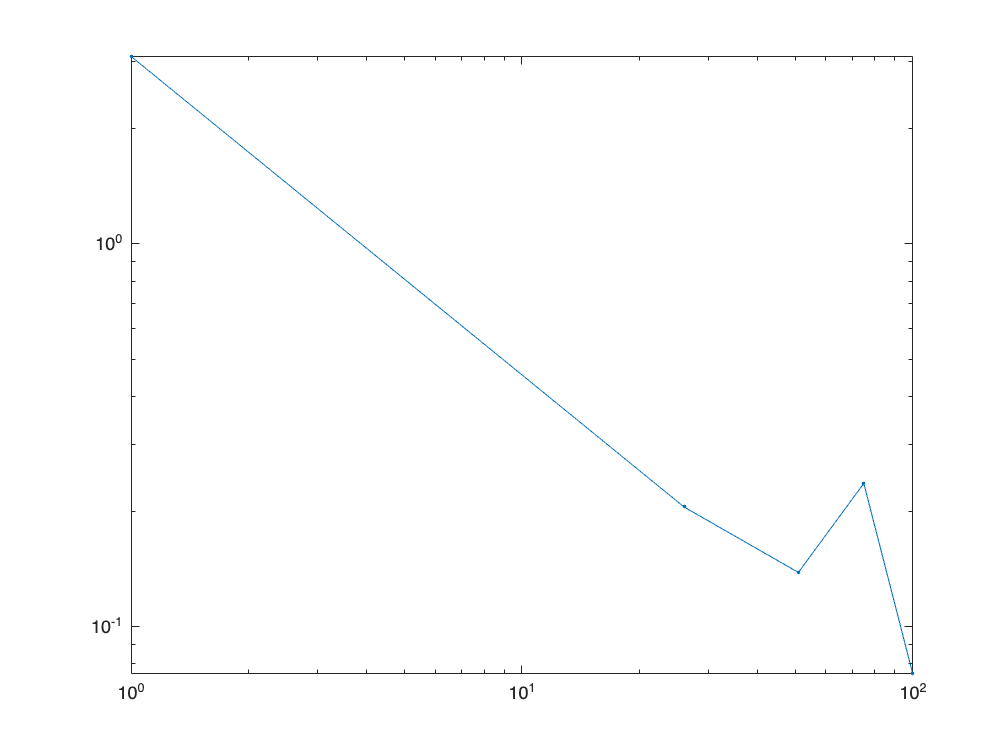

Berr = squeeze(pagenorm(Btrue-B,"fro"));
loglog(kk,Berr/norm(Btrue,"fro"),".-");

#### Theoretical barycenter

clear
n=2; % data dimension
k=10000; % number of matrices
r=n;
B=data(n,1,r)

B =     2.3268    4.5515
    4.5515    8.9207


A = data_scaled(B,k);
prob = convex_problem(A);

Bsqrt = multisqrtm(B);
mean(multisqrtm(pagemtimes(pagemtimes(Bsqrt,A),Bsqrt)),3) % fixed point

ans =     2.3244    4.5457
    4.5457    8.9068


getGradient(prob,B)

ans =     0.0375    0.0738
    0.0738    0.1451


getGradient(prob,prob.M.rand())

ans =    -0.2161   -2.0460
   -2.0460   -2.8209


#### Convergence to theoretical barycenter

clear
n=2; % data dimension
kk=round(logspace(0,3,10)); % number of matrices
r=n;
Btrue=data(n,1,r);
A = data_scaled(Btrue,kk(end));
for jk=1:length(kk)
    k=kk(jk);
    [B(:,:,jk),Bcost(jk),info(jk)] = cvx_solve(A(:,:,1:k));
end

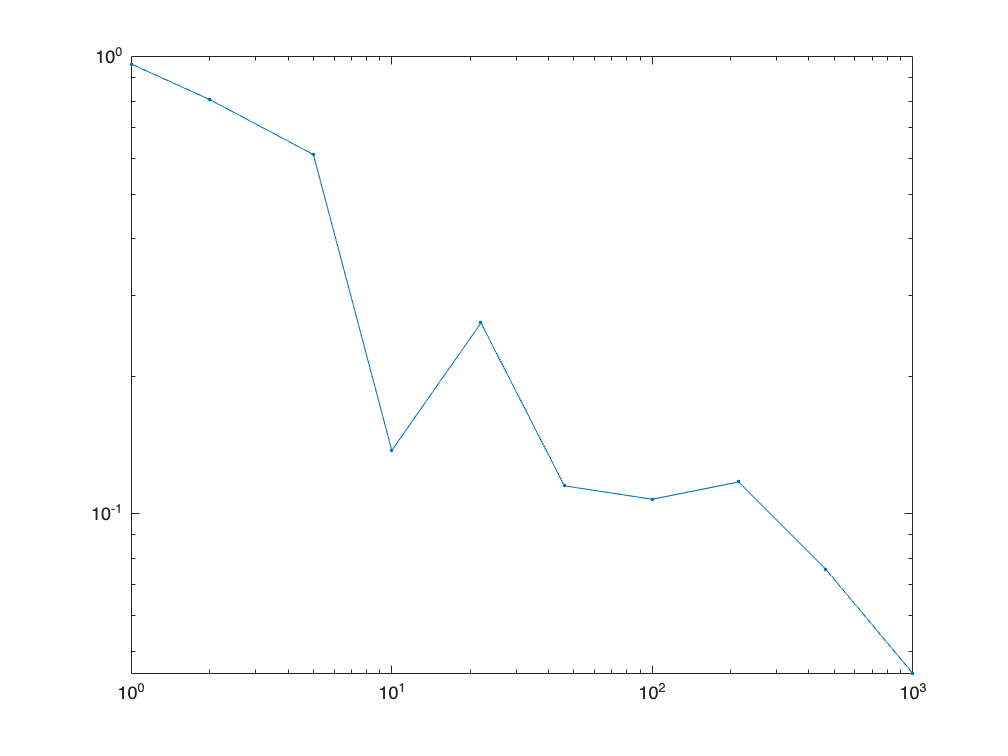

Berr = squeeze(pagenorm(Btrue-B,"fro"));
Berr_relat = Berr/norm(Btrue,"fro");
loglog(kk,Berr_relat,".-")

poly=polyfit(log(kk),log(Berr_relat),1);
hold on
loglog(kk,polyval(poly,log(kk)))

## Semi Definite Relaxation (SDR) problem

n=5;
k=7;
C=randn();
cvx_begin sdp
    variable XX( n*k, n*k ) symmetric
    minimize(-sum(C.*XX))
    B >= 0
    for j=1:k
        ids = (j-1)*n+(1:n);
        XX(ids,ids)==eye(n);
    end

cvx_end